# **Circuit Bode Plots**

## Circuit Bode 1

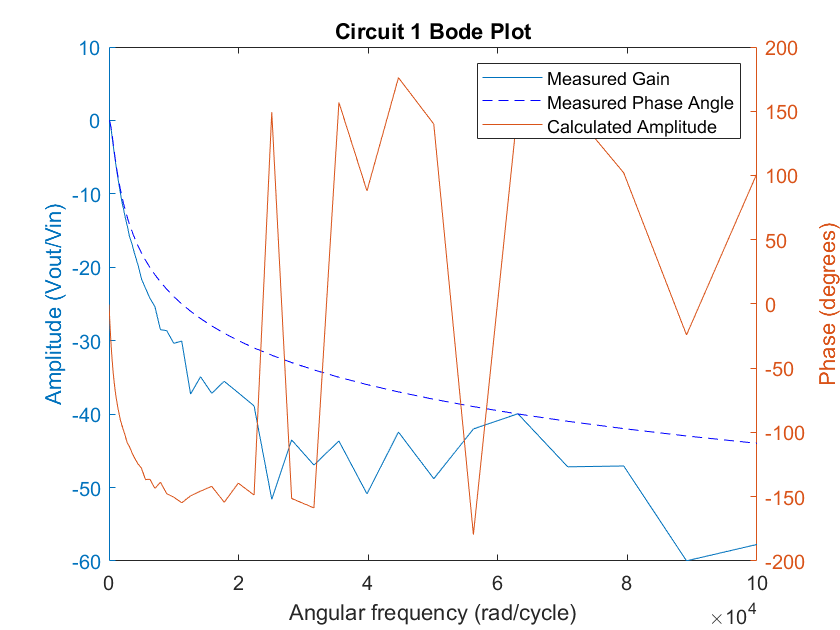

clf;
circuit_1_bode_data = csvread('circuit_1_bode.csv',3);
circuit_1_bode_freq = circuit_1_bode_data((1:99),1);
circuit_1_bode_gain = circuit_1_bode_data((1:99),2);
circuit_1_bode_phase = circuit_1_bode_data((1:99),3);

xlabel( "Angular frequency (rad/cycle)" )
title("Circuit 1 Bode Plot")

yyaxis left
plot(circuit_1_bode_freq,circuit_1_bode_gain);
ylabel( "Amplitude (Vout/Vin)" )
yyaxis right
plot(circuit_1_bode_freq, circuit_1_bode_phase);
ylabel( "Phase (degrees)" )

hold on;

yyaxis left

circuit_1_amplitude = 20 * log10(1./sqrt(1 + (0.00158 * circuit_1_bode_freq).^2));

plot(circuit_1_bode_freq,circuit_1_amplitude,'b');

legend("Measured Gain", "Measured Phase Angle", "Calculated Amplitude")

## Circuit Bode 2

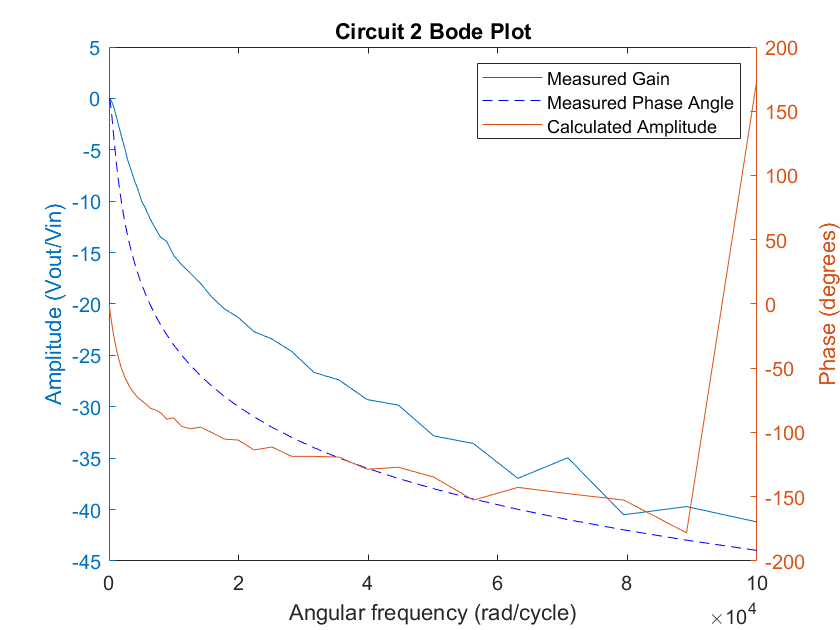

clf;
circuit_2_bode_data = csvread('circuit_2_bode.csv',3);
circuit_2_bode_freq = circuit_2_bode_data((1:99),1);
circuit_2_bode_gain = circuit_2_bode_data((1:99),2);
circuit_2_bode_phase = circuit_2_bode_data((1:99),3);

xlabel( "Angular frequency (rad/cycle)" )
title("Circuit 2 Bode Plot")

yyaxis left
plot(circuit_2_bode_freq,circuit_2_bode_gain);
ylabel( "Amplitude (Vout/Vin)" )
yyaxis right
plot(circuit_2_bode_freq, circuit_2_bode_phase);
ylabel( "Phase (degrees)" )

hold on;

yyaxis left

circuit_2_amplitude = 20 * log10(1./sqrt(1 + (0.00158 * circuit_2_bode_freq).^2));

plot(circuit_2_bode_freq,circuit_2_amplitude,'b');

legend("Measured Gain", "Measured Phase Angle", "Calculated Amplitude")

## Circuit Bode 3

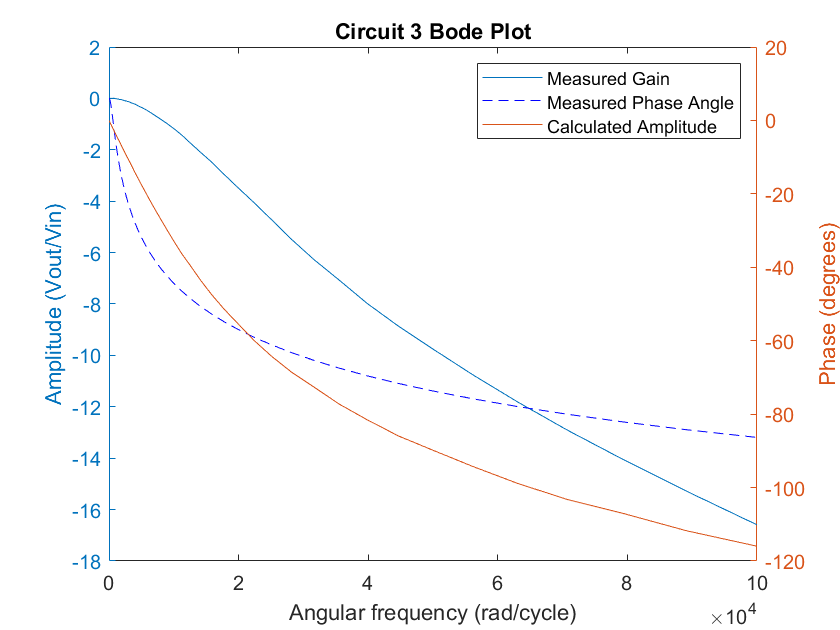

clf;
circuit_3_bode_data = csvread('circuit_3_bode.csv',3);
circuit_3_bode_freq = circuit_3_bode_data((1:99),1);
circuit_3_bode_gain = circuit_3_bode_data((1:99),2);
circuit_3_bode_phase = circuit_3_bode_data((1:99),3);

xlabel( "Angular frequency (rad/cycle)" )
title("Circuit 3 Bode Plot")

yyaxis left
plot(circuit_3_bode_freq,circuit_3_bode_gain);
ylabel( "Amplitude (Vout/Vin)" )
yyaxis right
plot(circuit_3_bode_freq, circuit_3_bode_phase);
ylabel( "Phase (degrees)" )

hold on;

yyaxis left

circuit_3_amplitude = 6 * log10(1./sqrt(1 + (0.00158 * circuit_3_bode_freq).^2));

plot(circuit_3_bode_freq,circuit_3_amplitude,'b');

legend("Measured Gain", "Measured Phase Angle", "Calculated Amplitude")

## Circuit Bode 4

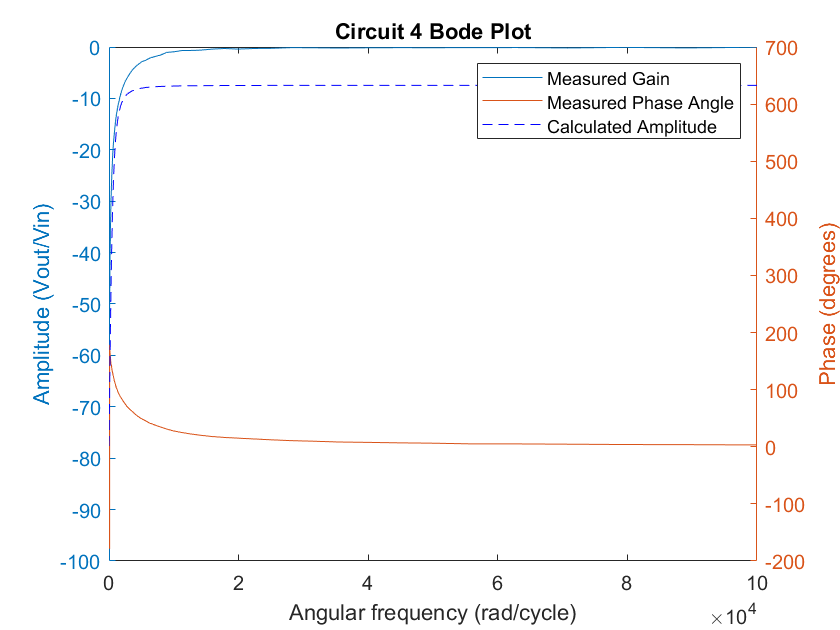

clf;
circuit_4_bode_data = csvread('circuit_4_bode.csv',3);
circuit_4_bode_freq = circuit_4_bode_data((1:99),1);
circuit_4_bode_gain = circuit_4_bode_data((1:99),2);
circuit_4_bode_phase = circuit_4_bode_data((1:99),3);

xlabel( "Angular frequency (rad/cycle)" )
title("Circuit 4 Bode Plot")

yyaxis left
plot(circuit_4_bode_freq,circuit_4_bode_gain);
ylabel( "Amplitude (Vout/Vin)" )
yyaxis right
plot(circuit_4_bode_freq, circuit_4_bode_phase);
ylabel( "Phase (degrees)" )

hold on;

circuit_4_amplitude = circuit_4_bode_freq./sqrt(1 + (0.00158 * circuit_4_bode_freq).^2);

plot(circuit_4_bode_freq,circuit_4_amplitude,'b');

legend("Measured Gain", "Measured Phase Angle", "Calculated Amplitude")

## Circuit Bode 5

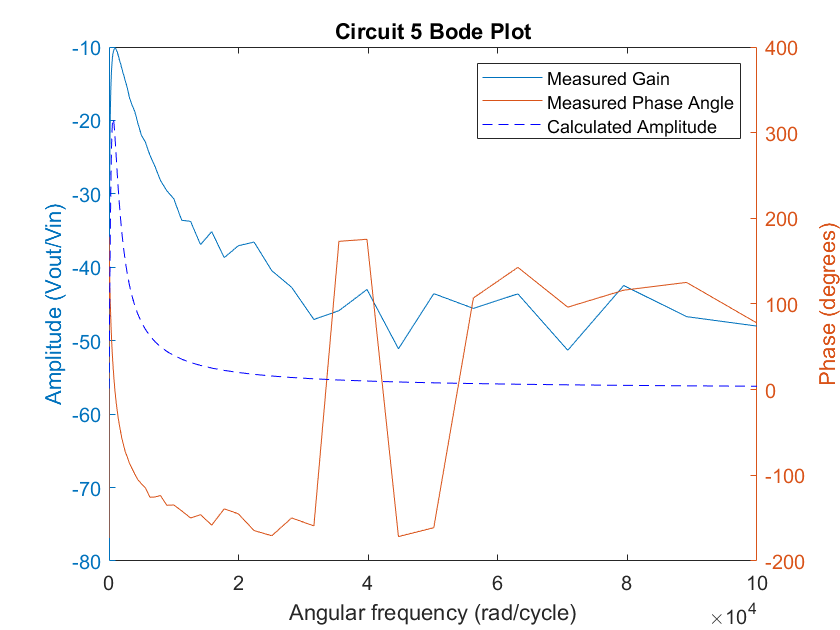

clf;
circuit_5_bode_data = csvread('circuit_5_bode.csv',3);
circuit_5_bode_freq = circuit_5_bode_data((1:99),1);
circuit_5_bode_gain = circuit_5_bode_data((1:99),2);
circuit_5_bode_phase = circuit_5_bode_data((1:99),3);

title("Circuit 5 Bode Plot")
xlabel( "Angular frequency (rad/cycle)" )

yyaxis left
plot(circuit_5_bode_freq,circuit_5_bode_gain);
ylabel( "Amplitude (Vout/Vin)" )
yyaxis right
plot(circuit_5_bode_freq, circuit_5_bode_phase);
ylabel( "Phase (degrees)" )

hold on;

circuit_5_amplitude = (1./sqrt(1 + (0.00158 * circuit_5_bode_freq).^2)) .* (circuit_5_bode_freq./sqrt(1 + (0.00158 * circuit_5_bode_freq).^2));

plot(circuit_5_bode_freq,circuit_5_amplitude,'b');

legend("Measured Gain", "Measured Phase Angle", "Calculated Amplitude")